f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);%.*sin(24*x-1);

x1 = lhsdesign(100,2);
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));


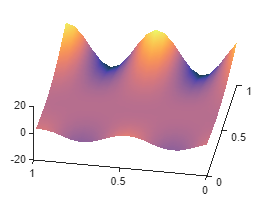

a = means.const(0);

q = kernels.EQ_Hess(1,[2 3]);%.periodic(2,5);

q.signn = eps;

Z = GP(a,q);

Z1 = Z.condition(x1,y1);

Z1 = Z1.train();

figure(1)
clf(1)
hold on
utils.plotSurf(Z1,[0 0],2,1,'CI',false)
view(-80,60)
plot3(x1(:,1),x1(:,2),y1,'+','MarkerSize',18)